addpath(genpath('signals'))
addpath('signal_proc_functions')
load('unit_impulse_response.mat', 'unit_impulse_response')

sample_rate = 256; %sample rate of UIR

pad = zeros(1, sample_rate * 20); % for padding signals with some zeros at the beginning and end

input = load('input_mixed_sine.mat');
output = load('output_mixed_sine.mat');

% resample input to same sample rate as UIR and truncate 
input_ds = resample(input.data, sample_rate, input.sample_rate);
input_ds = input_ds(5*sample_rate:310*sample_rate);

% zero recorded output and deconvolve
output_signal = output.data - mean(output.data);
output_signal = [pad, output_signal, pad];
recon = deconv(output_signal, unit_impulse_response);

% Truncate reconstruction and output for ease (they are long signals) 
recon = recon(1*sample_rate:350*sample_rate);
output_signal = output_signal(1*sample_rate:350*sample_rate);

% Make reconstruction and output signals the same length as the input
recon = recon(1:length(input_ds));
output_signal = output_signal(1:length(input_ds));

% Input, reconstruction, and output needs to be temporally aligned for phase comparison to work. 
% Make cross-correlogram and find lag of max correlation to align 
[input_recon_xcorr, lags] = xcorr(input_ds, recon, [], 'coeff');
[max_coeff, i_max_lag] = max(input_recon_xcorr)

max_coeff = 0.9283

i_max_lag = 68304

max_lag = lags(i_max_lag)

max_lag = -9777


recon = recon(abs(max_lag) + 1:end);
output_signal = output_signal(abs(max_lag)+1:end);
input_ds = input_ds(1:length(recon));

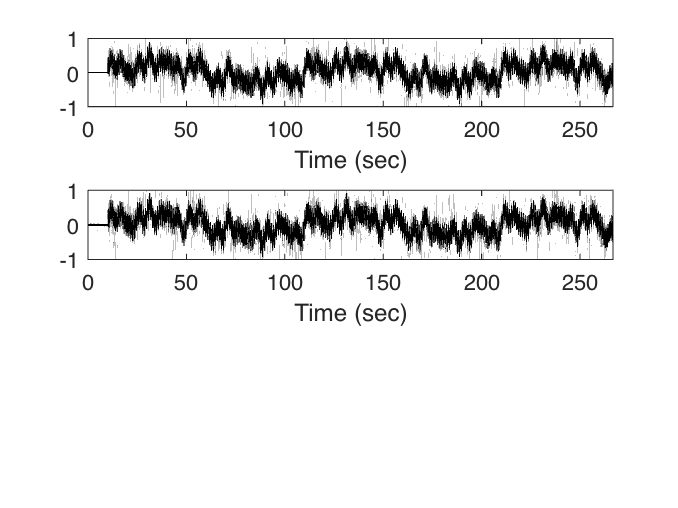

% Plot to see that the alignment worked
figure
subplot(3,1,1)
plot_signal(input_ds, sample_rate, 'sec', 'k')

subplot(3,1,2)
plot_signal(recon, sample_rate, 'sec', 'k')

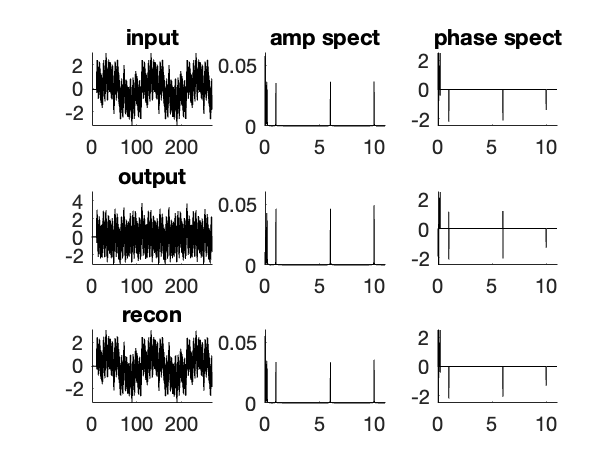

% normalize to z-score to make signals comparable in amplitude 
input_ds = norm_z(input_ds);
output_signal = norm_z(output_signal);
recon = norm_z(recon);

% set amp spectrum tolerance for inclusion in phase spectrum
tol = 1e-2;

% calculate amp spectrum and phase spectrum for input, output, and
% reconstruction
[f_input, y1_input] = fft_transform(input_ds, sample_rate);
[f_output, y1_output] = fft_transform(output_signal, sample_rate);
[f_recon, y1_recon] = fft_transform(recon, sample_rate);

phase_input = y1_input;
amp_input = abs(y1_input);
amp_input = amp_input/sum(amp_input);
phase_input(amp_input < tol) = 0;
phase_input = angle(phase_input);

phase_output = y1_output;
amp_output = abs(y1_output);
amp_output = amp_output / sum(amp_output);
phase_output(amp_output < tol) = 0;
phase_output = angle(phase_output);

phase_recon = y1_recon;
amp_recon = abs(y1_recon);
amp_recon = amp_recon / sum(amp_recon);
phase_recon(amp_recon < tol) = 0;
phase_recon = angle(phase_recon);

% Plot results
t = (0:length(input_ds)-1)/sample_rate; % time axis for plot 
figure
ax1 = subplot(3,3,1); hold('on')
title('input')
plot(t, input_ds, 'k')

ax2 = subplot(3,3,2); hold('on')
title('amp spect')
plot(f_input, amp_input, 'k')
ylim([0, 0.06])

ax3 = subplot(3,3,3); hold('on')
title('phase spect')
plot(f_input, phase_input, 'k')
ylim([-2.5, 2.5])


ax4 = subplot(3,3,4); hold('on')
title('output')
plot(t, output_signal, 'k')

ax5 = subplot(3,3,5); hold('on')
plot(f_output, amp_output, 'k')
ylim([0, 0.06])

ax6 = subplot(3,3,6); hold('on')
plot(f_output, phase_output, 'k')
ylim([-2.5, 2.5])

ax7 = subplot(3,3,7); hold('on')
title('recon')
plot(t, recon, 'k')

ax8 = subplot(3,3,8); hold('on')
plot(f_recon, amp_recon, 'k')
ylim([0, 0.06])

ax9 = subplot(3,3,9); hold('on')
plot(f_recon, phase_recon, 'k')
ylim([-2.5, 2.5])

linkaxes([ax2, ax3, ax5, ax6, ax8, ax9], 'x')
xlim([0,11])

% Run correlation analyses 

fprintf('\n correlation input vs. output')


 correlation input vs. output

[r, p] = corrcoef(input_ds, output_signal)

r =     1.0000    0.7032
    0.7032    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(input_ds))

n = 68304


fprintf('\n correlation input vs. recon')


 correlation input vs. recon

[r, p] = corrcoef(input_ds, recon)

r =     1.0000    0.9959
    0.9959    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(input_ds))

n = 68304


fprintf('\n correlation amplitude spectrum input vs. output')


 correlation amplitude spectrum input vs. output

[r, p] = corrcoef(amp_input, amp_output)

r =     1.0000    0.8406
    0.8406    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(amp_input))

n = 34153


fprintf('\n correlation amplitude spectrum input vs. recon')


 correlation amplitude spectrum input vs. recon

[r, p] = corrcoef(amp_input, amp_recon)

r =     1.0000    0.9973
    0.9973    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(amp_input))

n = 34153


fprintf('\n correlation phase spectrum input vs. output')


 correlation phase spectrum input vs. output

[r, p] = corrcoef(phase_input, phase_output)

r =     1.0000    0.0364
    0.0364    1.0000


p =     1.0000    0.0000
    0.0000    1.0000


fprintf('n = %i', length(phase_input))

n = 34153


fprintf('\n correlation phase spectrum input vs. recon')


 correlation phase spectrum input vs. recon

[r, p] = corrcoef(phase_input, phase_recon)

r =     1.0000    0.9998
    0.9998    1.0000


p =      1     0
     0     1


n = 34153

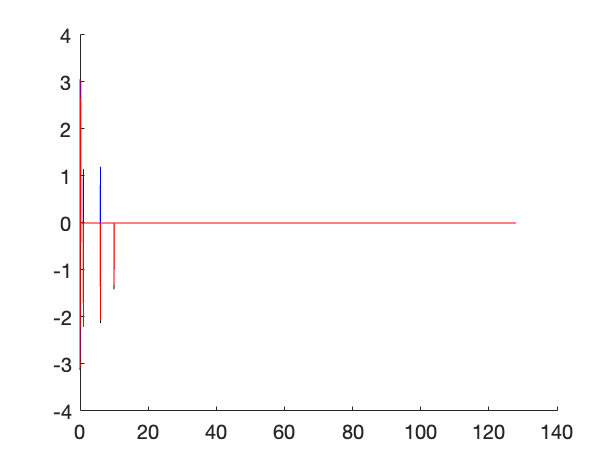

fprintf('n = %i', length(phase_input))